# Lactose Utilization Network of *Escherichia Coli *

% ensure that this is >10 for beta_g to be valid.
% concentrations are expressed in uM.

consts.glu = 50;
consts.tmg_e = 80;

% total LacI conc.
consts.rT = 0.4e-3;

% model params.
params.rho = 167.1;
params.beta_g = 65;
params.n = 2;

**Solve the system of ODEs.**

% time duration.
consts.tmax = 100;

% initial Cdk1 and Cyclin concentrations are 0.
consts.y_init = [0; 0];

% get ODE functions.
ode_funcs = lac_system_ode;

% solve ODE.
[ode_tout, x] = ode45(@(t,y) ode_funcs.dydt(t, y, consts, params), [0; consts.tmax], consts.y_init);

**Unpack and Plot the ODE solutions.**

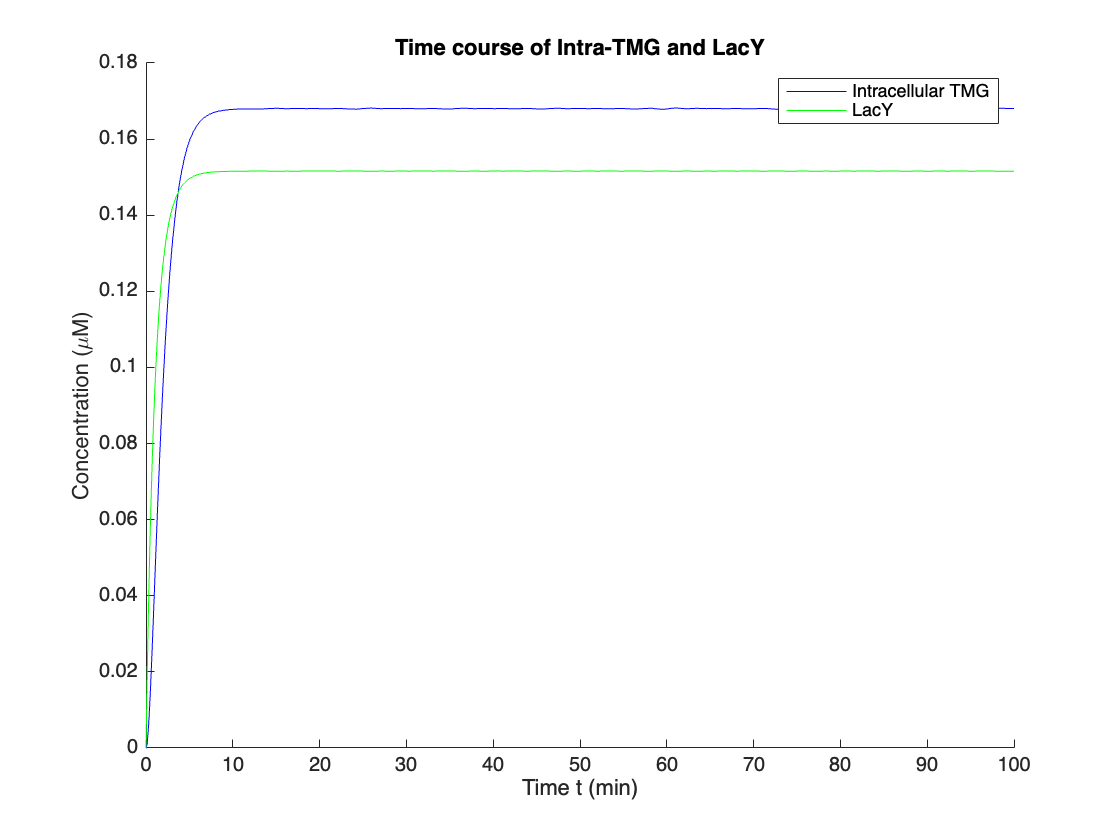

% unpack.
ode_tmgi = x(:, 1);
ode_lacy = x(:, 2);
% plot.
figure; hold on; zoom on;
plot(ode_tout, ode_tmgi, 'Color', 'blue');
plot(ode_tout, ode_lacy, 'Color', 'green');
title('Time course of Intra-TMG and LacY');
xlabel('Time t (min)');
ylabel('Concentration (\muM)');
legend('Intracellular TMG', 'LacY');

### Analytical Solution for Steady State

ode_funcs = lac_system_ode;
[ode_tmgi_nullcline, ode_lacy_nullcline] = ode_funcs.nullclines(consts, params);

$$lac\_i = \frac{1}{2500\,\left({{\mathrm{tmg}}_{i}}^{2}+1\right)}$$

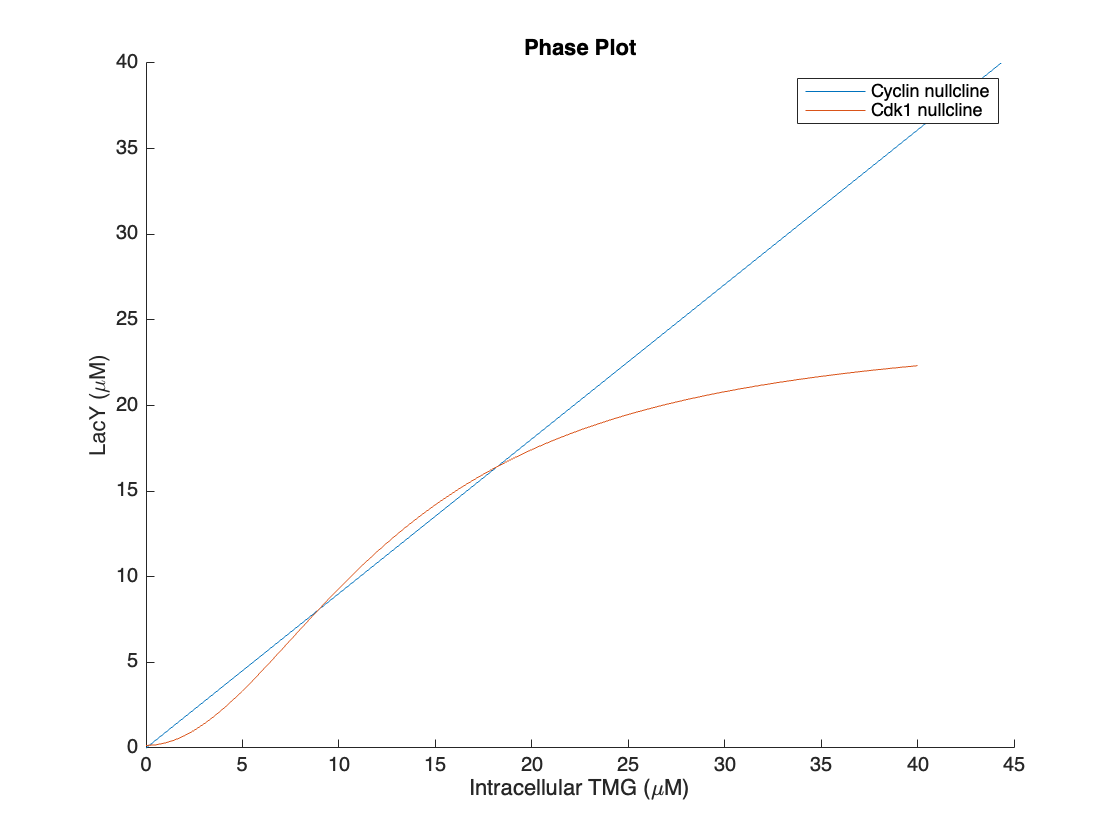


% plot nullclines.
figure; hold on; zoom on;
plot(double(subs(ode_tmgi_nullcline, sym('lac_y'), linspace(0, 40, 81))), 0:0.5:40);
plot(0:0.5:40, double(subs(ode_lacy_nullcline, sym('tmg_i'), linspace(0, 40, 81))));
title('Phase Plot');
xlabel('Intracellular TMG (\muM)');
ylabel('LacY (\muM)');
legend('Cyclin nullcline', 'Cdk1 nullcline');

PrettyFig;

PrettyFig is not found in the current folder or on the MATLAB path, but exists in:
    /Users/karthikd/Workspace/phd/code/modeling-biological-systems/ps2_collins-switch
    /Users/karthikd/Workspace/phd/code/modeling-biological-systems/ex3_harmonic-oscillator

Change the MATLAB current folder or add its folder to the MATLAB path.